clear
clc
close all

load('bem1_symetric ave Ede1 and Exo84'); %%wtede1sym and wtexo84sym

%total number of receptors
totnumreceptors=0; %JUST GENERIC
totnumgeneric=1000; %JUST GENERIC

%number of bins on the membrane
bins=100;

%Time step amount for each iteration
timestep=0.01;%secs

%total number of steps for the whole simulation
% totalsteps=200000/10;
totalsteps=200000;

simulationlength=timestep*totalsteps;

%circumference of a yeast cell in um
circumferenceofcell=10;%um

%maximum number of receptors per bin
maxrecperbin=floor((circumferenceofcell/bins)/.0031);

%Length of each bin
lengthofbin=circumferenceofcell/bins;%um
litersofbin=lengthofbin^3/ 1e15;%um^3->L


%Receptor Diffusion coefficient= membrane protein yeast
receptordiffusioncoeff=0.0024;%um^2/s

receptorhalflife=6;%6 minutes

%210222 to set up cargo/receptor inital location

range = (bins-1)/2;
finalcircum=circumferenceofcell+lengthofbin*(bins-bins);
distancerange=round((-range * finalcircum/bins):finalcircum/bins:(range*finalcircum/bins),2);
distancerange_tot=distancerange;

Actin pit= max of 5 min (initation is 30sec to 4 min and regular lifetime is 30sec to 1 min)

So I'm thinking if it wasn't internalized in 5 minutes then make a new actin pit

endopitdensity=0.9719; %0.9719 actinpit/um
endopitstd=0.314; %0.9719 actinpit/um
% endopittotal=floor(endopitdensity*circumferenceofcell);
endopittotal=floor(endopitdensity*circumferenceofcell);
endopittotalminmax=[floor((endopitdensity-endopitstd)*circumferenceofcell),floor((endopitdensity+endopitstd)*circumferenceofcell)];
endopit_maxtime=5*60; %5 minutes

[a,endopit_polarcap]=sort(abs(distancerange));
endopit_polarcap=sort(distancerange(endopit_polarcap(1:floor(bins*0.2))));
endopit_polarcapvsperiphery=0.5;

Frequency of exo per min= 24 **Johnson et al **

Frequency of exo per min = 2.7 **Carillo et al 2015**


$$#\;\textrm{of}\;\textrm{exo}\;\textrm{per}\;\textrm{minute}\;\times \;#\;\textrm{of}\;\textrm{seconds}\;\textrm{total}\;\times \frac{\;1\min }{60\sec }=\textrm{total}\;#\;\textrm{of}\;\textrm{exo}\;\textrm{events}\;\textrm{in}\;\textrm{this}\;\textrm{simulation}$$



$$\frac{\textrm{total}\;#\;\textrm{of}\;\textrm{exo}\;\textrm{events}\;\textrm{in}\;\textrm{this}\;\textrm{simulation}}{#\;\textrm{of}\;\textrm{timesteps}}=\textrm{probability}\;\textrm{of}\;\textrm{an}\;\textrm{exo}\;\textrm{event}\;\textrm{per}\;\textrm{timestep}$$



$$\begin{array}{l}
\frac{\textrm{events}}{\min }*\frac{1\min }{60\textrm{seconds}}*#\;\textrm{of}\;\textrm{seconds}=\textrm{number}\;\textrm{of}\;\textrm{events}\;\textrm{that}\;\textrm{should}\;\textrm{have}\;\textrm{happened}\\
\textrm{Chance}\;\textrm{of}\;\textrm{forming}\;\textrm{endocytic}\;\textrm{pit}=\frac{#\;\textrm{of}\;\textrm{ub}\;\textrm{bound}\;\textrm{receptors}\;\textrm{in}\;\textrm{bin}}{\textrm{Maximum}\;\textrm{number}\;\textrm{of}\;\textrm{receptors}\;\textrm{per}\;\textrm{bin}}
\end{array}$$


freqexo=2.7; %per minute % changed to 8, test 2.7
% freqexo=0;
timingexo=round(linspace(1,totalsteps,freqexo/60*simulationlength+1));
timingexo=timingexo(2:end);
freqendo=freqexo *2 ;% 16;%JUST GENERIC
%freqendo=0;
timingendo=round(linspace(1,totalsteps,freqendo/60*simulationlength+1));
timingendo=timingendo(2:end);


exocytosispro=avecenterresize(wtbem1sym,bins,find(abs(distancerange)==min(abs(distancerange)),1));
exocytosispro=cumsum(exocytosispro);
exocytosispro= exocytosispro/max( exocytosispro);


Carrillo et al diameter of endo vesicle=132nm exo vesicle=155nm

Circumference

Endo= 414.69nm->0.41469um

Exo=486.95nm->0.48695

floor(vesicle_circumference/lengthofbind)=# of bins for each event

lengthendobin=1; %floor(0.41469/lengthofbin);
% endohererange_bin=ceil(bins/2)+(ceil(-lengthendobin/2):ceil(-lengthendobin/2+lengthendobin-1));
lengthexobin=2; %floor(0.41469/lengthofbin);%floor(0.48695/lengthofbin);
lengthCIEbin=1;

%movement probability based on
moveprob=receptordiffusioncoeff*timestep/(lengthofbin)^2

moveprob = 0.0024


%Struct to keep track of receptors
%diffusion is what bin it moved to and what time
%This one is just the receptors on the membrane
%JUST GENERIC
receptor=struct('pheromone',[],'phos',[],'ub',[],...
    'timeonmembrane',[], 'currlocation',[],'diffusion',[],...
    'ubbound',[]);

%This one is all of the receptors (internalized)
receptor_internalized=struct('pheromone',[],'phos',[],'ub',[],...
    'timeonmembrane',[], 'currlocation',[],'diffusion',[],...
    'ubbound',[]);

generic(totnumgeneric)=struct('ub',[],...
    'timeonmembrane',[], 'currlocation',[],'diffusion',[],...
    'ubbound',[]);

generic_internalized=struct('ub',[],...
    'timeonmembrane',[], 'currlocation',[],'diffusion',[],...
    'ubbound',[]);

Lifetime of the receptor setup

x=0:timestep:receptorhalflife*2;%0:timestep:receptorhalflife*2;
ypdf = gampdf(x,2.72,12);
ycdf=gamcdf(x,2.72,12);
ypdf=ypdf/max(ypdf);
% ypdf(7)/ypdf(end);

figure();
plot(x,ypdf)
hold on
cumsumpdf=cumsum(ypdf);
cumsumpdf=cumsumpdf/max(cumsumpdf);
plot(x,cumsumpdf)
legend('pdf','cdf')
halfline=refline(0,0.5);
halfline.Color='k';
halfline=xline(6);
halfline.Color='k';

Set up Receptors

generic_placement=discretize(1:totnumgeneric,bins);

%randomly set up time on membrane from 0 to 12
%if time=12-> interalize because t1/2 with pheromone
% initialize receptor struct
for i=1:size(generic,2)
    generic(i).timeonmembrane=0;
    generic(i).currlocation=round(distancerange(generic_placement(i)),2);
    generic(i).diffusion= [generic(i).timeonmembrane;generic(i).currlocation];
    generic(i).pheromone=0;
    generic(i).phos=0;
    generic(i).ub=0;
    generic(i).endopit=0;

    %     receptor(i).timeonmembrane=0;
    %     receptor(i).currlocation=receptor_placement(i);
    %     receptor(i).diffusion= [receptor(i).timeonmembrane;receptor(i).currlocation];
    %     receptor(i).pheromone=0;
    %     receptor(i).phos=0;
    %     receptor(i).ub=0;

end



%add pheromone somehow

pheromone

based on 200917 lab update slide 7: 2.4e-4 receptors have phe bound

previously 0.002 for each microsecond unknown source maybe based on koff/Kd


$$1\;\textrm{molecule}\;\textrm{of}\;\textrm{phe}*\frac{1\textrm{mole}}{6\ldotp 023\textrm{E23}\;\textrm{molecules}}*\frac{1\;\textrm{bin}}{\textrm{liters}\;\textrm{per}\;\textrm{bin}}$$



$$P\;\textrm{of}\;\textrm{bindphe}\;\textrm{per}\;\textrm{microsecond}\times #\;\textrm{of}\;\textrm{microseconds}\;\textrm{for}\;\textrm{each}\;\textrm{second}\times #\;\textrm{of}\;\textrm{seconds}\;\textrm{in}\;\textrm{each}\;\textrm{timestep}=\textrm{total}\;\textrm{probability}\;\textrm{of}\;\textrm{binding}\;\textrm{to}\;\textrm{occur}$$



$$\begin{array}{l}
{\textrm{kon}:\;0\ldotp 185s}^{-1} {\textrm{uM}}^{-1} *#\;\textrm{of}\;\textrm{seconds}\;\textrm{in}\;\textrm{each}\;\textrm{timestep}*\textrm{uM}\;\textrm{of}\;\textrm{one}\;\textrm{receptor}\\
\textrm{koff}:1e-3s^{-1} 
\end{array}$$


% uMreceptorperbin=(1/6.023E23)/litersofbin*10^6;
uMpheromoneperbin=((1/6.023E23)/litersofbin)*10^6;
pbind=(0.185*timestep*uMpheromoneperbin)/maxrecperbin;%# binding events per timestep time; base it on location
punbind=0.001*timestep;


$$\begin{array}{l}
K_{\textrm{cat}} =#\;\textrm{of}\;\textrm{molecules}\;\textrm{of}\;\textrm{product}\;\textrm{per}\;\textrm{enzyme}\;\textrm{per}\;\textrm{time}\;\left(\textrm{seconds}\right)\\
K_{\textrm{cat}} \;\textrm{Ste2}\;\textrm{phosphorylation}\;\textrm{without}\;\textrm{pheromone}=7\ldotp 4e-4s^{-1} \\
K_{\textrm{cat}} \;\;\textrm{Ste2}\;\textrm{phosphorylation}\;\textrm{with}\;\textrm{pheromone}=0\ldotp 1s^{-1} \\
0\ldotp 1s^{-1} *#\;\textrm{of}\;\textrm{seconds}\;\textrm{in}\;\textrm{each}\;\textrm{timestep}
\end{array}$$



$$\textrm{Ubiqunination}=\textrm{degradation}\;\textrm{rate}=3\ldotp 2*{10}^{-3} s^{-1}$$


[Ste2]*kinternalization=ksyn

2000*1e6/(litersofbin*6.02e23)=8.0324e+06=[Ste2]

8.0324e+06*2.9e-4= 2.3294e+03<- k of synthesis per second

phoswophe=7.4e-4*timestep;
phoswphe=0.1*timestep;
% deg=3.2e-3*timestep*0.2*0.001;
phosprob = 1e-1;

ubprob=3.2e-3*timestep;


2.7 exo events per minute

4 molecules of ste2 in steady state per second*60=240 per minute/2.7=88.89

% syn=4*5; %4 molecules per sec Yi et al. (2003)
syn=0;%88.89; %receptors per event%JUST GENERIC
%%%%
syn_gen=20;

membranerec=hist([receptor.currlocation],distancerange);
membranegen=hist([generic.currlocation],[distancerange]);

membraneallgen=NaN(totalsteps,bins);
ubmembraneallgen=NaN(totalsteps,bins);

% pheromonemembrane=NaN(totalsteps,bins);
% phosmembrane=NaN(totalsteps,bins);
membranesize=zeros(totalsteps,1);
endopitmembrane=zeros(totalsteps,bins);
locationbinnumber=1:bins;
% exolocations=zeros(totalsteps,bins);
endolocationall=[];
exolocationall=[];
CIElocationall=[];
synthesize_prev=0;
roundnum =2;

distancerange=round((-range * finalcircum/bins):finalcircum/bins:(range*finalcircum/bins),2);

%make struct to keep endopits
endopit=struct('timeonmembrane',[], 'currlocation',[], 'numberofub',[], 'diffusion',[]);
endopit_interalized=struct('timeonmembrane',[], 'currlocation',[], 'numberofub',[], 'diffusion',[]);

endopitinitilize = randsample(distancerange,endopittotal) ;
for endopitint=1:endopittotal
    endopit(endopitint).currlocation=endopitinitilize(endopitint);
    endopit(endopitint).timeonmembrane=0;
end

endopitinitilize = randsample(endopit_polarcap,floor(endopittotal*endopit_polarcapvsperiphery)) ;
endopitinitilize = [endopitinitilize,randsample(distancerange(~ismember(distancerange,endopit_polarcap)),...
    floor(endopittotal*endopit_polarcapvsperiphery))] ;
for endopitint=1:length(endopitinitilize)
    endopit(endopitint).currlocation=endopitinitilize(endopitint);
    endopit(endopitint).timeonmembrane=ceil(normrnd(50,40));
    while endopit(endopitint).timeonmembrane<0
        endopit(endopitint).timeonmembrane=ceil(normrnd(60,15));
    end
    endopit(endopitint).diffusion= [endopit(endopitint).timeonmembrane;endopit(endopitint).currlocation];
end


for j=1:totalsteps

    %Keeping track of the size of the membrane
    membranesize(j)=bins;
    sizeofmembrane=find(isnan(membranerec)==0 , 1, 'last');
    locationbinnumber=1:bins;

    %Initialize the membrane for this timestep to nonNaN rec+gen
    membraneallgen(j,1:bins)=zeros(1,bins);
    membraneallgen_empty(j,1:bins)=zeros(1,bins);


    %Initialize the membrane for this timestep to nonNaN rec+gen
    ubmembraneallgen(j,1:bins)=zeros(1,bins);
    endopitmembrane(j,ismember(distancerange,[endopit.currlocation]))=1;

    %If endo happens
    if any(timingendo==j)

        endopit_maturity=find(60<[endopit.timeonmembrane] & [endopit.timeonmembrane]<endopit_maxtime);
        matureendopitbin=find(hist([endopit(endopit_maturity).currlocation],distancerange));

        %if endopit has been there too long
        endopit_old=find([endopit.timeonmembrane]>=endopit_maxtime);

        %if theres mature endopits and no super old endopits
        if isempty(endopit_maturity)==0 && isempty(endopit_old)==1

            %quantify the amount of modifications per bin normalized
            cargo_location=(ubmembraneallgen(j-1,:))./maxrecperbin;

            %of the mature endo pits, which has the most modified cargo
            cargo_bin=matureendopitbin(find(cargo_location(matureendopitbin)==max(cargo_location(matureendopitbin))));

        else
            cargo_location=(ubmembraneallgen(j-1,:))./maxrecperbin;
            cargo_location( ismember(distancerange,[endopit.currlocation]))=0;

            if sum(cargo_location)==0
                cargo_location=(ubmembraneallgen(j-1,:))./maxrecperbin;
                cargo_location( ismember(distancerange,[endopit.currlocation]))=0;
            end
            cargo_bin=(find(cargo_location==max(cargo_location)));
        end

        %if there's more than one potential endopit to internalize
        if length(cargo_bin)>1
            endobin= randsample(cargo_bin,1);
        else
            endobin=cargo_bin;
        end

        endolocationinternalizegen=[];
        shiftedmembrane=circshift(distancerange,ceil(bins/2)-endobin);
        endohere=shiftedmembrane(ceil(bins/2)+(ceil(-lengthendobin/2):ceil(-lengthendobin/2+lengthendobin-1)));

        shiftedmembrane_bins=circshift(locationbinnumber,ceil(bins/2)-endobin);
        endohere_bins=shiftedmembrane_bins(ceil(bins/2)+(ceil(-lengthendobin/2):ceil(-lengthendobin/2+lengthendobin-1)));
        endohere=shiftedmembrane(ceil(bins/2)+(ceil(-lengthendobin/2):ceil(-lengthendobin/2+lengthendobin-1)));

        %Distance

        endolocationall(end+1).location=endohere;
        endolocationall(end).generic=membranegen(endohere_bins);
        endolocationall(end).genericub=ubmembraneallgen(j-1,endohere_bins);
        endolocationall(end).timestep=j;
        endolocationinternalize=[];

        %Find which endopits are where endo is happening and delete
        %them
        if any(find(ismember([endopit.currlocation],endohere)))
            endopit(find(ismember([endopit.currlocation],endohere)))=[];
        end

        %Find which receptors to internalize
        endolocationinternalizegen=find(ismember([generic.currlocation],endohere));
        endolocationinternalizegen= sort(endolocationinternalizegen);


        %remove receptors from that location
        for p=size(endolocationinternalizegen,2):-1:1
            if isempty(generic_internalized(1).timeonmembrane)==1
                generic_internalized=generic(endolocationinternalizegen(p));
            else
                generic_internalized(size(generic_internalized,2)+1)=generic(endolocationinternalizegen(p));

            end
            generic(endolocationinternalizegen(p))=[];

        end


        %if you're endocytosing at the end (either end)
        if any(ismember(endohere,distancerange(1))) || any(ismember(endohere,distancerange(end)))
            shift=0;
            %remove values in distance range to the right (positive
            %numbers)
            endolocationgeneric=[];
            distancerange=distancerange(1:end-sum(endohere>1));
            distancerange=distancerange(1+sum(endohere<1):end);
            endopitshift=[];

            %endocytosis is to the left
        elseif endohere(1)<0
            shift=1;
            endolocationgeneric=find([generic.currlocation]<endohere(1));
            endopitshift=find([endopit.currlocation]<endohere(1));
            distancerange=distancerange(lengthendobin+1:end);

            %endocytosis is to the right
        elseif endohere(1)>0
            shift=-1;
            endolocationgeneric=find([generic.currlocation]>endohere(end));
            endopitshift=find([endopit.currlocation]>endohere(end));
            distancerange=distancerange(1:bins-lengthendobin);
        end


        for k=1:size(endolocationgeneric,2)
            generic(endolocationgeneric(k)).currlocation= round(generic(endolocationgeneric(k)).currlocation+shift*lengthendobin*lengthofbin,roundnum);

            %                 generic(endolocationgeneric(k)).currlocation=endoshiftmembrane(generic(endolocationgeneric(k)).currlocation);
            %                 updatediffusiondata=[generic(endolocationgeneric(k)).timeonmembrane;generic(endolocationgeneric(k)).currlocation];
            %                 generic(endolocationgeneric(k)).diffusion=[generic(endolocationgeneric(k)).diffusion,updatediffusiondata];
            %                 generic(endolocationgeneric(k)).diffusion=generic(endolocationgeneric(k)).diffusion+shift*lengthendobin*lengthofbin;
        end

        endolocationgeneric=[];

        if isempty(endopitshift)==0
            endopitsthatneedtomove=sort(endopitshift);
            for endopitmoving=length(endopitsthatneedtomove):-1:1
                if ismember(endopit(endopitsthatneedtomove(endopitmoving)).currlocation,endohere)
                    endopit(endopitsthatneedtomove(endopitmoving))=[];
                else
                    endopit(endopitsthatneedtomove(endopitmoving)).currlocation=round(endopit(endopitsthatneedtomove(endopitmoving)).currlocation+shift*lengthendobin*lengthofbin,2);

                end
            end
        end
        %update basics
        bins=bins-lengthendobin;
        pheromone

        membranesize(j)=bins;

        %use the product of bem1 and exo84 since cdc42 would also be a
        %requirement.  :JBK

        exosteep = wtbem1sym.*wtexo84sym;
        exosteep = exosteep./sum(exosteep);

        exocytosispro=avecenterresize(exosteep,bins,find(abs(distancerange)==min(abs(distancerange)),1,'last'));
        exocytosispro=cumsum(exocytosispro);
        exocytosispro= exocytosispro/max( exocytosispro);

        membranegen=histcounts([generic.currlocation],[distancerange,distancerange(end)+lengthofbin]);

        circumferenceofcell=abs(distancerange(1))+abs(distancerange(end));
        % endopittotal=ceil(endopitdensity*circumferenceofcell);
        [a,endopit_polarcap]=sort(abs(distancerange));
        endopit_polarcap=sort(distancerange(endopit_polarcap(1:floor(bins*0.2))));

        %recenter distancerange find where the center
        %is (minimum absolute) and see if it's half way
        %through the array
        while find(min(abs(distancerange))==abs(distancerange),1)~= floor(length(distancerange)/2)
            if abs(distancerange(1))> distancerange(end)

                genericmove=find(ismember([generic.currlocation],distancerange(1)));
                for move=1:length(genericmove)
                    generic(genericmove(move)).currlocation=round(distancerange(end)+lengthofbin,roundnum);
                end
                if any(ismember([endopit.currlocation],distancerange(1)))
                    endopitmove=find(ismember([endopit.currlocation],distancerange(1)));
                    for move=1:length(endopitmove)
                        endopit(endopitmove(move)).currlocation=round(distancerange(end)+lengthofbin,roundnum);
                    end
                end
                distancerange=round([distancerange(2:end),distancerange(end)+lengthofbin],roundnum);


            elseif abs(distancerange(1))< distancerange(end)
                genericmove=find(ismember([generic.currlocation],distancerange(end)));
                for move=1:length(genericmove)
                    generic(genericmove(move)).currlocation=round(distancerange(1)-lengthofbin,roundnum);
                end
                if any(ismember([endopit.currlocation],distancerange(end)))
                    endopitmove=find(ismember([endopit.currlocation],distancerange(end)));
                    for move=1:length(endopitmove)
                        endopit(endopitmove(move)).currlocation=round(distancerange(1)-lengthofbin,roundnum);
                    end
                end
                distancerange=round([distancerange(1)-lengthofbin,distancerange(1:end-1)],roundnum);
            end
        end
        for k=1:size(endolocationgeneric,2)
            %                 generic(endolocationgeneric(k)).currlocation=round(generic(endolocationgeneric(k)).currlocation+shift*lengthendobin*lengthofbin,2);
            %                 generic(endolocationgeneric(k)).currlocation=endoshiftmembrane(generic(endolocationgeneric(k)).currlocation);
            updatediffusiondata=[generic(endolocationgeneric(k)).timeonmembrane;generic(endolocationgeneric(k)).currlocation];
            generic(endolocationgeneric(k)).diffusion=[generic(endolocationgeneric(k)).diffusion,updatediffusiondata];
        end
    end

    %exocytosis
    if any(timingexo==j)
        %Find where exocytosis will happen
        indextf=find(exocytosispro<rand);
        while isempty(indextf)==1
            indextf=find(exocytosispro<rand);
        end

        exobin=indextf(end);

        exohere=[];
        shiftedmembrane=circshift(distancerange,ceil(bins/2)- exobin);
        exohere=shiftedmembrane(ceil(bins/2):ceil(bins/2)+ceil(lengthexobin-1));

        exolocationall(end+1).location=[exohere];

        %move currentlocation of receptors> than location of exo
        %First find them
        %if they are to the left of the polar cap
        if exohere(1)<0
            shift=-1;
            exolocationgeneric=find([generic.currlocation]<=exohere(end));
            exopitshift=find([endopit.currlocation]<exohere(end));
            distancerange=round([distancerange(1)-lengthexobin*lengthofbin:lengthofbin:distancerange(1)-lengthofbin, distancerange],roundnum);

            %if they are to the left of the polar cap
        elseif exohere(1)>=0
            shift=1;
            exolocationgeneric=find([generic.currlocation]>=exohere(1));
            exopitshift=find([endopit.currlocation]>exohere(1));
            distancerange=round([distancerange,distancerange(end)+lengthofbin:lengthofbin:distancerange(end)+lengthexobin*lengthofbin],roundnum);
        end

        for k=1:size(exolocationgeneric,2)
            generic(exolocationgeneric(k)).currlocation=round(generic(exolocationgeneric(k)).currlocation+shift*lengthexobin*lengthofbin,roundnum);
            %             generic(exolocationgeneric(k)).diffusion=generic(exolocationgeneric(k)).diffusion+shift*lengthexobin*lengthofbin;
        end

        generic=exocytose(generic,syn_gen,exohere);

        if isempty(exopitshift)==0
            for endopitshift=1:length(exopitshift)
                endopit(exopitshift(endopitshift)).currlocation=round(endopit(exopitshift(endopitshift)).currlocation+shift*lengthexobin*lengthofbin,2);
            end
        end

        %update basics
        bins=bins+lengthexobin;

        pheromone

        membranesize(j)=bins;

        exocytosispro=avecenterresize(wtbem1sym,bins,find(abs(distancerange)==min(abs(distancerange)),1,'last'));
        exocytosispro=cumsum(exocytosispro);
        exocytosispro= exocytosispro/max( exocytosispro);


        membranegen=histcounts([generic.currlocation],[distancerange,distancerange(end)+lengthofbin]);

        circumferenceofcell=abs(distancerange(1))+abs(distancerange(end));
        % endopittotal=ceil(endopitdensity*circumferenceofcell);
        [a,endopit_polarcap]=sort(abs(distancerange));
        endopit_polarcap=sort(distancerange(endopit_polarcap(1:floor(bins*0.2))));

        %             recenter distancerange
        while find(min(abs(distancerange))==abs(distancerange),1)~= floor(length(distancerange)/2)
            if abs(distancerange(1))> distancerange(end)

                genericmove=find(ismember([generic.currlocation],distancerange(1)));
                for move=1:length(genericmove)
                    generic(genericmove(move)).currlocation=round(distancerange(end)+lengthofbin,roundnum);
                end
                if any(ismember([endopit.currlocation],distancerange(1)))
                    endopitmove=find(ismember([endopit.currlocation],distancerange(1)));
                    for move=1:length(endopitmove)
                        endopit(endopitmove(move)).currlocation=round(distancerange(end)+lengthofbin,roundnum);
                    end
                end
                distancerange=round([distancerange(2:end),distancerange(end)+lengthofbin],roundnum);


            elseif abs(distancerange(1))< distancerange(end)
                genericmove=find(ismember([generic.currlocation],distancerange(end)));
                for move=1:length(genericmove)
                    generic(genericmove(move)).currlocation=round(distancerange(1)-lengthofbin,roundnum);
                end
                if any(ismember([endopit.currlocation],distancerange(end)))
                    endopitmove=find(ismember([endopit.currlocation],distancerange(end)));
                    for move=1:length(endopitmove)
                        endopit(endopitmove(move)).currlocation=round(distancerange(1)-lengthofbin,roundnum);
                    end
                end
                distancerange=round([distancerange(1)-lengthofbin,distancerange(1:end-1)],roundnum);
            end
        end

        if length(distancerange_tot)<length(distancerange)

            diff=bins-length(distancerange_tot);
            wheretoinsertbin=find(~ismember(distancerange,distancerange_tot))

            membraneallgen(:,wheretoinsertbin)=NaN(size(membraneallgen,1),lengthexobin);
            ubmembraneallgen(:,wheretoinsertbin)=NaN(size(membraneallgen,1),lengthexobin);
            endopitmembrane(:,wheretoinsertbin)=zeros(size(membraneallgen,1),lengthexobin);

            %if there's a difference (there should be)
            if diff==1
                %find where the difference is
                if find(~ismember(distancerange,distancerange_tot))==1

                    membraneallgen=[NaN(size(membraneallgen,1),diff),membraneallgen];
                    ubmembraneallgen=[NaN(size(ubmembraneallgen,1),diff),ubmembraneallgen];
                    endopitmembrane=[NaN(size(endopitmembrane,1),diff),endopitmembrane];
                else
                    membraneallgen=[membraneallgen,NaN(size(membraneallgen,1),diff)];
                    ubmembraneallgen=[ubmembraneallgen,NaN(size(ubmembraneallgen,1),diff)];
                    endopitmembrane=[endopitmembrane,NaN(size(endopitmembrane,1),diff)];
                end
            else
                membraneallgen=[NaN(size(membraneallgen,1),ceil(lengthexobin/2)),membraneallgen,NaN(size(membraneallgen,1),ceil(lengthexobin/2))];
                ubmembraneallgen=[NaN(size(ubmembraneallgen,1),ceil(lengthexobin/2)),ubmembraneallgen,NaN(size(ubmembraneallgen,1),ceil(lengthexobin/2))];
                endopitmembrane=[zeros(size(endopitmembrane,1),ceil(lengthexobin/2)),endopitmembrane,zeros(size(endopitmembrane,1),ceil(lengthexobin/2))];
            end

            distancerange_tot=round(distancerange,roundnum);
        end
        for k=1:size(exolocationgeneric,2)

            updatediffusiondata=[generic(exolocationgeneric(k)).timeonmembrane;generic(exolocationgeneric(k)).currlocation];
            generic(exolocationgeneric(k)).diffusion=[generic(exolocationgeneric(k)).diffusion,updatediffusiondata];
        end

    end
    if length([endopit.currlocation]) ~= length(unique([endopit.currlocation]))
        [C,ia,ic]=unique([endopit.currlocation]);
        repeatendopit=find([endopit.currlocation]==C(find(hist(ic,1:length(ic))>=2)));
        endopit(randsample(repeatendopit,1))=[];
    end

    % For Generic
    for i=1:size(generic,2)

        genericbinnumber=find(ismember(distancerange,generic(i).currlocation));




        %check to see if it binds ubiquitin
        %if its not currently bound to ubiquitin and is phosphorylated
        if  generic(i).ub==0 && generic(i).phos==1 && rand<ubprob

            generic(i).ub=1;
            generic(i).ubbound=[generic(i).timeonmembrane;generic(i).currlocation];
            currentub=hist([generic([find([generic.ub]==1)]).currlocation],distancerange);

            %forming an endocytic pit based on #ub/maxub
            if rand< currentub(genericbinnumber)/maxrecperbin && ...
                    any([endopit.currlocation]==generic(i).currlocation)==0 && ...
                    size(endopit,2)<endopittotalminmax(end)

                endopit(size(endopit,2)+1).currlocation=generic(i).currlocation;
                endopit(size(endopit,2)).timeonmembrane=0;
            end
        end

        % Check if generic gets phosphorylated, which is a prerequisite
        % for ubiquitination
        if generic(i).phos==0 && rand < phosprob
            generic(i).phos = 1;
        end



        %%%%%%%%%%%%%% Diffusion
        if rand<moveprob && generic(i).endopit==0

            %center the membrane
            shiftedmembrane=circshift(membranegen,ceil(bins/2)-genericbinnumber);

            %Shift Left (-1)
            if rand<=.5
                if rand<1-(sum(shiftedmembrane(ceil(bins/2)-1))/maxrecperbin) %left
                    shift_diff=-1;
                end
                %Shift Right (+1)
            else
                if rand<1-(sum(shiftedmembrane(ceil(bins/2)+1))/maxrecperbin) %right
                    shift_diff=1;
                end
            end

            %while you're shifting
            while exist('shift_diff')
                if (generic(i).currlocation<=distancerange(1)) || (generic(i).currlocation>=distancerange(end))
                    shiftedlocation=circshift(distancerange,...
                        ceil(bins/2)-genericbinnumber);
                    generic(i).currlocation=round(shiftedlocation(ceil(bins/2)+shift_diff),2);
                else
                    generic(i).currlocation=round(generic(i).currlocation+shift_diff*lengthofbin,2);
                end

                updatediffusiondata=[generic(i).timeonmembrane;generic(i).currlocation];
                generic(i).diffusion=[generic(i).diffusion,updatediffusiondata];
                membranegen=hist([generic.currlocation],[distancerange]);
                clear shift_diff
                genericbinnumber=find(ismember(round(distancerange,2),round(generic(i).currlocation,2)));
                if generic(i).ub==1 && any([endopit.currlocation]==generic(i).currlocation )==1 && rand<0.3
                    generic(i).endopit=1;
                end

            end
        end

        generic(i).timeonmembrane=generic(i).timeonmembrane+timestep;

    end

    % If two endopits are in the same locations
    if length([endopit.currlocation]) ~= length(unique([endopit.currlocation]))
        [C,ia,ic]=unique([endopit.currlocation]);
        repeatendopit=find([endopit.currlocation]==C(find(hist(ic,1:length(ic))>=2)));
        endopit(randsample(repeatendopit,1))=[];
    end


    %find out if more endopits are needed on polar cap or
    %periphery so first I'm going to find what percentage are at
    %the polar cap
    endopitpercent_polarcap=sum(ismember(endopit_polarcap,[endopit.currlocation]))/endopittotal;% percent of endopits on polar cap


    %       Add More Endopits if necessary
    if endopitpercent_polarcap<0.5 && endopittotal>length([endopit]) && j>1

        cargo_distribution=zeros(bins,1);

        cargo_location=(ubmembraneallgen(j-1,:))./maxrecperbin;

        %if there are more than 20% of the pit on the polar cap, go to
        %the periphery
        if endopitpercent_polarcap>0.5
            cargo_distribution(~ismember(distancerange,endopit_polarcap))=cargo_location(find(~ismember(distancerange,endopit_polarcap)));

            %                 otherwise its on the polar cap
        else
            cargo_distribution(ismember(distancerange,endopit_polarcap))=cargo_location(find(ismember(distancerange,endopit_polarcap)));
        end
        %
        %for however many I need to add to make up for the difference
        cargo_distribution( ismember(distancerange,[endopit.currlocation]))=0;
        cargo_distribution( ismember(distancerange,round([endopit.currlocation]+lengthofbin, roundnum)))=0;
        cargo_distribution( ismember(distancerange,round([endopit.currlocation]-lengthofbin, roundnum)))=0;
        endopit_bin=find(max(cargo_distribution)==cargo_distribution);
        if length(endopit_bin) >1
            endopit_bin=randsample(endopit_bin,1);
        end
        %use the actin distribution (either on the periphery or polar cap) normalize it and chose a random location to put an endo pit
        endopitlocation=distancerange(endopit_bin);
        endopit(end+1).currlocation=round(endopitlocation,roundnum);
        endopit(end).timeonmembrane=0;
        endopit(end).diffusion= [endopit(end).timeonmembrane;endopit(end).currlocation];
        stuckinpit=find(ismember([generic.currlocation],[endopit(end).currlocation]));
        if isempty(stuckinpit)==0
            for stuck=1:length(stuckinpit)
                if rand<0.3
                    generic(stuckinpit(stuck)).endopit=1;
                end
            end
        end
        clear stuckinpit cargo_distribution endopit_bin

        if length([endopit.currlocation]) ~= length(unique([endopit.currlocation])) || any([endopit.currlocation])~=any(distancerange)
            [C,ia,ic]=unique([endopit.currlocation]);
            repeatendopit=find([endopit.currlocation]==C(find(hist(ic,1:length(ic))>=2)));
            pick1endopit=randsample(repeatendopit,1);
            endpit_interalized=endopit(pick1endopit);
            endopit(pick1endopit)=[];
        end
        endopitpercent_polarcap=sum(ismember(endopit_polarcap,[endopit.currlocation]))/endopittotal;% percent of endopits on polar cap

    end

    %Age Endopits appropriately
    for endopitint=1:size(endopit,2)
        endopit(endopitint).timeonmembrane=endopit(endopitint).timeonmembrane+timestep;

    end

    %update housekeeping/record keeping things, only arrays based on
    membraneallgen(j,:)=hist([generic.currlocation],[distancerange_tot]);
    ubmembraneallgen(j,:)=hist([generic([find([generic.ub]==1)]).currlocation],[distancerange_tot]);
    endopitmembrane(j,ismember(round(distancerange_tot,2),[endopit.currlocation]))=ones(1,size(endopit,2));

end

% savefig(allfigs,'201102_45min_endomore20recmore3mintime.fig')
save(['220826_intdiffusiontest_error.mat'])


membraneresults=struct('type_of_membrane',[{'generic all'}, {'generic ub bound'}],...
    'raw',[{membraneallgen},{ubmembraneallgen}],...
    'centered',[],'NaNto0',[],'mean',[]);
alltime=timestep*[1:totalsteps];

for m=1:size(membraneresults,2)
    %     membranecenter(l,:)=
    membraneresults(m).centered=membraneresults(m).raw;
    membranemean=mean( membraneresults(m).centered,1,'omitnan');
    membraneresults(m).mean=membranemean;
    clear membranecenter membranemean
end
endomembrane_norm=(sum(endopitmembrane))/sum(sum(endopitmembrane));


%Graph generic stuff
%genericall=2 and genericub=6
% [find({membraneresults.type_of_membrane}==['generic all']),find({membraneresults.type_of_membrane}=={'generic ubiquitin bound'})]
figure();
% plotgenerics=[2,6];
legendthings=[];
for i=1:2
    %     gen=plotgenerics(i)
    subplot(3,1,1)
    plot(distancerange_tot(1,:),[membraneresults(i).mean])
    xlabel('Distance from Polar Cap (um)')
    title('Mean Protein Distribution')
    xticks([-5:5])
    grid on
    legendthings=[legendthings,{[membraneresults(i).type_of_membrane]}];
    if i==2
        legend(legendthings,'Location','bestoutside')
    end
    hold on
    %make a images
    subplot(3,1,1+i)
    imagesc(0:timestep:simulationlength,distancerange_tot(1,:) ,transpose([membraneresults(i).centered]))
    ylabel('Distance from Polar Cap (um)')
    xlabel('Time (minutes)')
    title('Receptors Over Time')
    xticks([0:60:simulationlength])
    xticklabels(num2cell(0:simulationlength/60))
    colorbar
    title([membraneresults(i).type_of_membrane, ' Receptors'])
end

figure();
subplot(3,2,[1 2])
imagesc(0:timestep:simulationlength,distancerange_tot(1,:),transpose(endopitmembrane));
ylabel('Distance from Polar Cap (um)')
xlabel('Time (minutes)')
title('Receptors Over Time')
xticks([0:60:simulationlength])
xticklabels(num2cell(0:simulationlength/60))
title('Endopits Location Through Time')
colorbar
subplot(3,2,[3 4])
imagesc(0:timestep:simulationlength,distancerange_tot(1,:),transpose(sum(endopitmembrane,2)))
title('Total Amount EndoPits on the Membrane')
ylabel('Distance from Polar Cap (um)')
xlabel('Time (minutes)')
title('Receptors Over Time')
xticks([0:60:simulationlength])
xticklabels(num2cell(0:simulationlength/60))
colorbar
subplot(3,2,5)
histogram(sum(endopitmembrane,2))
title('Distribution of Amount of Endopits')
xlabel('Amount of Endopits')
ylabel('Frequency')
subplot(3,2,6)
bar(distancerange_tot(1,:),sum(endopitmembrane,1))
title('EndoPits location on the membrane')
xticks([-5:5])
xlabel('Distance from Polar Cap (um)')



figure();
subplot(2,1,1);
colorm=colormap(cool(size(endolocationall,2)));
for i=1:size(endolocationall,2)
    scatter(mean(endolocationall(i).location),  sum(endolocationall(i).genericub),...
        sum(endolocationall(i).generic)/1.5,colorm(i,:),'filled','MarkerFaceAlpha',0.5)
    hold on
    internalizedendo(i)=sum(endolocationall(i).generic);
end

Error using scatter
Value must be a vector of positive numeric type or nan.

title('Endocytosis Events')
xlabel('Distance from the Polar Cap')
ylabel({'Amount of Ub-Bound';'Protein Internalized'})
h=colorbar;
ylabel(h, 'Event Order')
h.Ticks = [0,1];
h.TickLabels={'Beginning','Ending'};
% ylim([0 maxrecperbin*2])
% txt = 'Size Cooresponds to # Protein Internalized';
% text(distancerange(end)-2,maxrecperbin,txt)
annotation('textbox', [0.65, 0.8, 0.2, 0.1], 'String',...
    {'Size Cooresponds to','# Protein Internalized'},'FitBoxToText','on','FontSize',6)
subplot(2,1,2)
histogram([endolocationall.location],round(min(distancerange_tot(:,1)):lengthofbin:max(distancerange_tot(:,end)+lengthofbin),2))
hold on
histogram([exolocationall.location],round(min(distancerange_tot(:,1)):lengthofbin:max(distancerange_tot(:,end)+lengthofbin),2))
title('Vesicle Trafficking Locations')
xlabel('Distance from the Polar Cap')
ylabel('Frequency of Events')
legend('Endo','Exo')

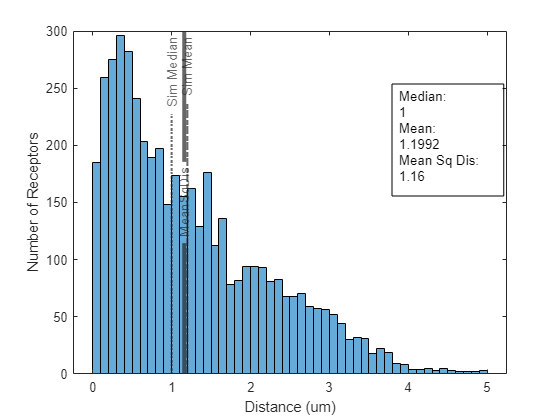


int_diffusion=[{generic_internalized.diffusion},{generic.diffusion}];

lengthofdiff=cellfun(@length,int_diffusion);
% simulationlength

for i=1:length(int_diffusion)
    %look at one protein's
    diff_ind=cell2mat([int_diffusion(1,i)]);
    diff_ind=round(diff_ind(2,:),2);
    membrane_center=round(circshift(distancerange_tot(1,:),floor(sizeofmembrane/2-find(ismember(distancerange_tot(1,:),diff_ind(1))))),2);
    diffusiondiff=find(ismember(round(membrane_center,1),round(diff_ind(end),1)));
    meansqdiff(i)=abs(sizeofmembrane/2-diffusiondiff)*lengthofbin;
end
%calculate actual
actualdiffusion=2 * 0.0029 * simulationlength;
figure();
histogram(meansqdiff,[min(meansqdiff):lengthofbin:max(meansqdiff)])
% title({'Mean Square Displacement of each Receptor',...
%     [num2str(totnumreceptors), ' Receptors, ',num2str(simulationlength),' Seconds Total ', num2str(timestep),' Time Step ', num2str(windowsize), ' Bins'],...
%     [num2str(lengthendobin),' endo ',num2str(lengthexobin),' exo 2.7 freq ',num2str(receptordiffusioncoeff),' diffusion ',num2str(circumferenceofcell),'um circum']})
xlabel('Distance (um)')
ylabel('Number of Receptors')
dim = [.7 .5 .2 .3];
annotation('textbox',dim,'String',[{'Median: ',num2str(median(meansqdiff)),...
    'Mean: ',num2str(mean(meansqdiff)),...
    'Mean Sq Dis: ',num2str(actualdiffusion*lengthofbin)}],'FitBoxToText','on');
a=xline(median(meansqdiff),':','Sim Median');
a.LabelHorizontalAlignment = 'center';
a.LineWidth=1.5;
b=xline(mean(meansqdiff),'-.','Sim Mean');
b.LabelHorizontalAlignment = 'center';
b.LineWidth=1.5;
c=xline(actualdiffusion*lengthofbin ,'-','MeanSqDis');
c.LabelHorizontalAlignment = 'center';
c.LabelVerticalAlignment = 'middle';
c.LineWidth=3;

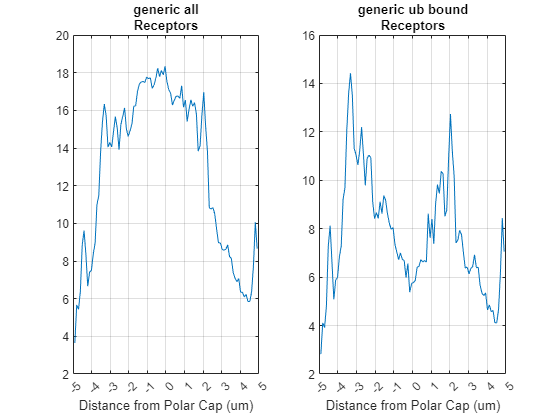

figure();


for i=1:size(membraneresults,2)
    subplot(1,2,i)

    lenbinplot=size([membraneresults(i).raw],2);
    range = ( lenbinplot-1)/2;
    finalcircum=circumferenceofcell+lengthofbin*(lenbinplot-membranesize(1));
    distancerange=(-range * finalcircum/lenbinplot):finalcircum/lenbinplot:(range*finalcircum/lenbinplot);

    plot(distancerange,[membraneresults(i).mean])
    xlabel('Distance from Polar Cap (um)')
    title({membraneresults(i).type_of_membrane 'Receptors'})
    xticks([-5:5])
    grid on
end

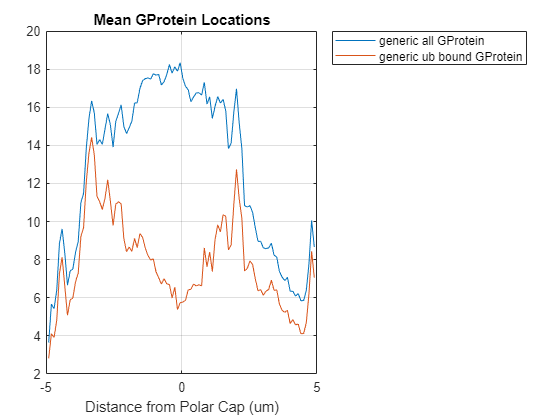

figure();
legendthings=[];
for i=1:size(membraneresults,2)

    lenbinplot=size([membraneresults(i).raw],2);
    range = ( lenbinplot-1)/2;
    finalcircum=circumferenceofcell+lengthofbin*(lenbinplot-membranesize(1));
    distancerange=(-range * finalcircum/lenbinplot):finalcircum/lenbinplot:(range*finalcircum/lenbinplot);

    plot(distancerange,[membraneresults(i).mean])
    xlabel('Distance from Polar Cap (um)')
    legendthings=[legendthings,{[membraneresults(i).type_of_membrane ' GProtein']}];
    grid on
    hold on
end
legend(legendthings,'Location','bestoutside')
% legendthings.Location='BestOutside'
title('Mean GProtein Locations')

figure();
legendthings=[];
% x=[distancerange(1),distancerange(end),distancerange(end),distancerange(1)]
% y=[0,0,max([membraneresults(1).mean])+max([membraneresults(1).mean])*0.1,max([membraneresults(1).mean])+max([membraneresults(1).mean])*0.1]

x=[distancerange,-distancerange]

x =    -4.9005   -4.8015   -4.7025   -4.6035   -4.5045   -4.4055   -4.3065   -4.2075   -4.1085   -4.0095   -3.9105   -3.8115   -3.7125   -3.6135   -3.5145   -3.4155   -3.3165   -3.2175   -3.1185   -3.0195   -2.9205   -2.8215   -2.7225   -2.6235   -2.5245   -2.4255   -2.3265   -2.2275   -2.1285   -2.0295   -1.9305   -1.8315   -1.7325   -1.6335   -1.5345   -1.4355   -1.3365   -1.2375   -1.1385   -1.0395   -0.9405   -0.8415   -0.7425   -0.6435   -0.5445   -0.4455   -0.3465   -0.2475   -0.1485   -0.0495


y=[(zeros(1,length(distancerange))),((max([membraneresults(2).mean])+max([membraneresults(2).mean]).*0.1).*ones(1,length(distancerange)))];
map=[transpose(linspace(0.7,1,20)),transpose(linspace(0.7,1,20)),transpose(linspace(0.7,1,20))]

map =     0.7000    0.7000    0.7000
    0.7158    0.7158    0.7158
    0.7316    0.7316    0.7316
    0.7474    0.7474    0.7474
    0.7632    0.7632    0.7632
    0.7789    0.7789    0.7789
    0.7947    0.7947    0.7947
    0.8105    0.8105    0.8105
    0.8263    0.8263    0.8263
    0.8421    0.8421    0.8421


colormap(map)
a=patch(transpose(x),transpose(y),transpose([([endomembrane_norm]),fliplr([endomembrane_norm])]))

a =   Patch with properties:

    FaceColor: 'interp'
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 80 81 … ]
     Vertices: [200×2 double]

  Show all properties


colorbar
legendthings= {['Endocytic Pits']}

legendthings = 1×1 cell array
    {'Endocytic Pits'}


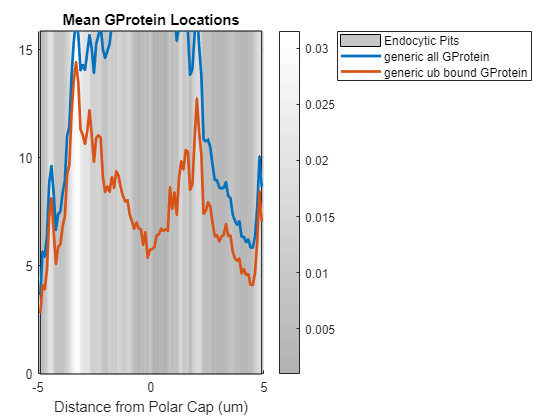


hold on
for i=1:size(membraneresults,2) %(not including endopit because that's background)

    lenbinplot=size([membraneresults(i).raw],2);
    range = ( lenbinplot-1)/2;
    finalcircum=circumferenceofcell+lengthofbin*(lenbinplot-membranesize(1));
    distancerange=(-range * finalcircum/lenbinplot):finalcircum/lenbinplot:(range*finalcircum/lenbinplot);


    plot(distancerange,[membraneresults(i).mean], 'LineWidth',2)
    xlabel('Distance from Polar Cap (um)')
    legendthings=[legendthings,{[membraneresults(i).type_of_membrane ' GProtein']}];
    grid on
    hold on
end
legend(legendthings,'Location','bestoutside')
% legendthings.Location='BestOutside'
title('Mean GProtein Locations')
ylim([0,max([membraneresults(2).mean])+max([membraneresults(2).mean])*0.1])

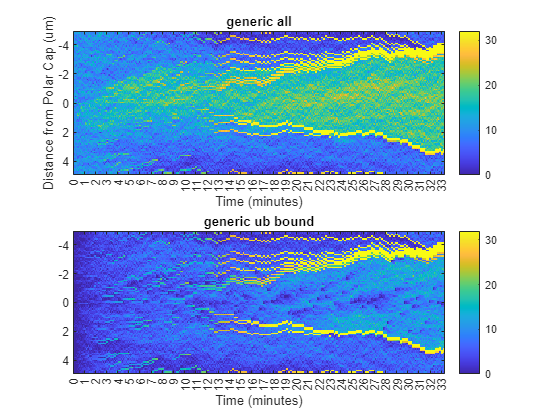

figure();
pli=0;
for i=1:size(membraneresults,2)
    pli=pli+1;
    subplot(size(membraneresults,2),1,pli)

    lenbinplot=size([membraneresults(i).raw],2);
    range = ( lenbinplot-1)/2;
    finalcircum=circumferenceofcell+lengthofbin*(lenbinplot-membranesize(1));
    distancerange=(-range * finalcircum/lenbinplot):finalcircum/lenbinplot:(range*finalcircum/lenbinplot);

    imagesc(0:timestep:simulationlength,distancerange ,transpose([membraneresults(i).centered]))
    if i==ceil((size(membraneresults,2)-1)/2)
        ylabel('Distance from Polar Cap (um)')
    end
    xlabel('Time (minutes)')
    title('Receptors Over Time')
    xticks([0:60:simulationlength])
    xticklabels(num2cell(0:simulationlength/60))
    colorbar
    title([membraneresults(i).type_of_membrane])
end

% struct('Cargo',[{'Receptor'},{'Generic'}])
% membraneresults=struct('type_of_membrane',[{'all'},{'generic all'},{'pheromone bound'},{'6X phos bound'},{'ubiquitin bound'}, {'generic ubiquitin bound'},{'EndocyticPit'}],...
%     'raw',[{membraneallrec},{membraneallgen}, {pheromonemembrane},{phosmembrane},{ubmembrane},{endopitmembrane}],...
%     'centered',[],'NaNto0',[],'mean',[]);
whenubbound=[receptor.ubbound];
whenubboundint=[receptor_internalized.ubbound];
whenubbound_gen=[generic.ubbound];
whenubboundint_gen=[generic_internalized.ubbound];


## Receptor figure


% figure();
% whenubbound=[receptor.ubbound];
% scatter(whenubbound(end,:),whenubbound(1,:), 'filled','MarkerEdgeColor','none','MarkerFaceAlpha',0.1)
% hold on
% whenubboundint=[receptor_internalized.ubbound];
% scatter(whenubboundint(end,:),whenubboundint(1,:), 'filled','MarkerEdgeColor','none','MarkerFaceAlpha',0.1)
% title('Time and Location Ubiquitin Binds')
% a=legend('On the membrane','Internalized');
% a.Location='bestoutside';
% ylabel('Time on the membrane (minutes)')
% xlabel('Distance from Polar Cap (um)')
% yticks([0:60:60*12])
% yticklabels(num2cell(0:12))
% % xlim([0,bins])
% %

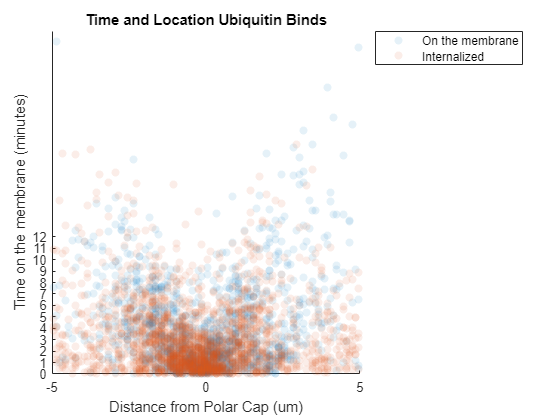

figure();
scatter(whenubbound_gen(end,:),whenubbound_gen(1,:), 'filled','MarkerEdgeColor','none','MarkerFaceAlpha',0.1)
hold on
scatter(whenubboundint_gen(end,:),whenubboundint_gen(1,:), 'filled','MarkerEdgeColor','none','MarkerFaceAlpha',0.1)
title('Time and Location Ubiquitin Binds')
a=legend('On the membrane','Internalized');
a.Location='bestoutside';
ylabel('Time on the membrane (minutes)')
xlabel('Distance from Polar Cap (um)')
yticks([0:60:60*12])
yticklabels(num2cell(0:12))

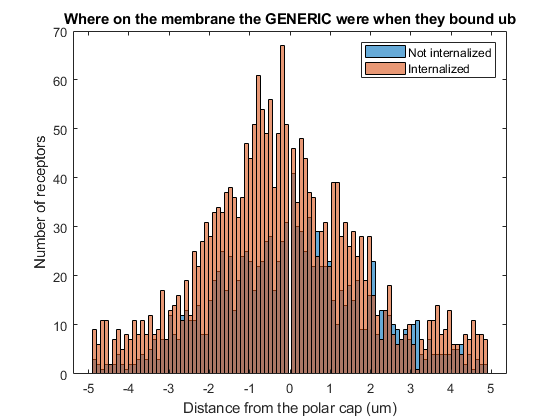

% xlim([0,bins])

figure;
histogram(whenubbound_gen(2,:),distancerange)
hold on
histogram(whenubboundint_gen(2,:),distancerange)
legend('Not internalized', 'Internalized')
title('Where on the membrane the GENERIC were when they bound ub')
xlabel('Distance from the polar cap (um)')
ylabel('Number of receptors')


figure;
counts1 = histc(whenubbound_gen(2,:),distancerange)                                    % Histogram For ‘d1’

counts1 =      3     2     1     2     2     2     4     2     1     2     2     3     4     3     5     7     3     7     7    12     8     7    12    13    11    11    14     8     8    15    19    21    25    17    24    13    19    24    25    23    17    22    23    27    28    17    23    27    31     0


counts2 = histc(whenubboundint_gen(2,:),distancerange)

counts2 =      9     6    11    11     2     7     9     5     8     7    11     8    11     8    12     8     9    17     7    13    14    16    11    19    12    25    22    27    31    28    33    34    33    37    38    36    32    36    47    44    51    61    54    49    56    38    49    67    51     0


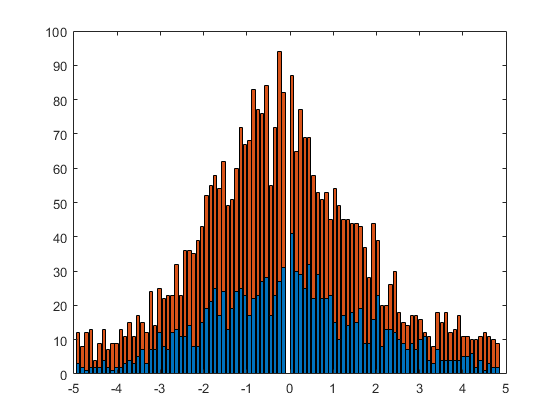



bar(distancerange, [counts1;counts2], 'stacked')

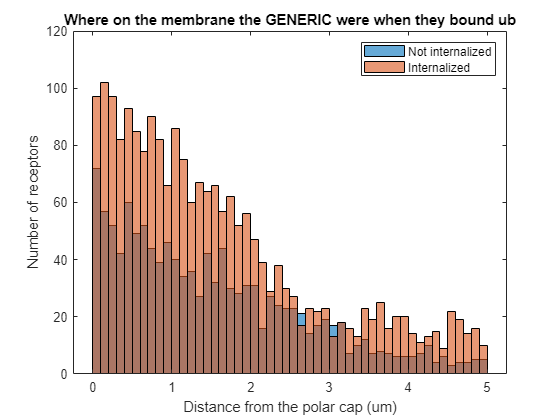


figure;
% histogram(whenubboundint(end,:),bins);
% subplot(1,2,1)
% histogram(abs(whenubbound(2,:)),0:ceil(max(abs(whenubbound(2,:)))))
% hold on
% histogram(abs(whenubboundint(2,:)),0:ceil(max(abs(whenubboundint(2,:)))))
% legend('Not internalized', 'Internalized')
% title('Where on the membrane the RECEPTORS were when they bound ub')
% xlabel('Distance from the polar cap (um)')
% ylabel('Number of receptors')
% subplot(1,2,2)
% whenubbound_gen=[generic.ubbound];
% whenubboundint_gen=[generic_internalized.ubbound];

histogram(abs(whenubbound_gen(2,:)),0:lengthofbin:ceil(max(abs(whenubbound_gen(2,:)))))
hold on
histogram(abs(whenubboundint_gen(2,:)),0:lengthofbin:ceil(max(abs(whenubboundint_gen(2,:)))))
legend('Not internalized', 'Internalized')
title('Where on the membrane the GENERIC were when they bound ub')
xlabel('Distance from the polar cap (um)')
ylabel('Number of receptors')

save('fastphos_jbk.mat', "endolocationall", "whenubbound_gen", "whenubboundint_gen", "membraneresults" );

for q = 1:size(endolocationall, 2);
    endolocxy(q,1) = endolocationall(q).location;
    endolocxy(q,2) = endolocationall(q).generic;
end


figure;
% scatter(endolocationall(:,1), endolocationall(:,2), 'filled','MarkerEdgeColor','none','MarkerFaceAlpha',0.7)
scatter(endolocxy(:,1), endolocxy(:,2), 'filled','MarkerEdgeColor','none','MarkerFaceAlpha',0.7)
title('Location and amount of Cargo Receptor for each endo')
% a=legend('On the membrane','Internalized');
% a.Location='bestoutside';
ylabel('Number of Fully Cargoed Receptors')
xlabel('Distance from Polar Cap (um)')
% xlim([0,bins])

figure();
subplot(2,1,1)
cargoreceptorinternalized=find([generic_internalized.ub]==1);
histogram( [generic_internalized(cargoreceptorinternalized).timeonmembrane],0:60:12*60);
xticks([0:60:60*12])
xticklabels(num2cell(0:12))
title('Receptors Time on the Membrane When Interalized');
xlabel('Time on the Membrane (min)')
ylabel('# of Receptors Internalized')
%
% subplot(2,2,3)
% lifetimeofrecsim=cumsum(hist([receptor_internalized.timeonmembrane],0:60:12*60));
% plot(0:60:12*60,lifetimeofrecsim)
% xticks([0:60:60*12])
% xticklabels(num2cell(0:12))
% % yticks([-1 -0.8 -0.2 0 0.2 0.8 1])
% xlabel('Time in minutes')
% title('Cumulative: Receptors Time on the Membrane When Interalized');
% xlabel('Time on the Membrane (min)')
% ylabel('# of Receptors Internalized')

subplot(2,1,2)
x=0:timestep:receptorhalflife*2;%0:timestep:receptorhalflife*2;
lifetimeofrecsim=cumsum(hist([generic_internalized.timeonmembrane],0:60:12*60));
plot(0:12,lifetimeofrecsim/max(lifetimeofrecsim))
xticks([0:12])
xticklabels(num2cell(0:12))
% yticks([-1 -0.8 -0.2 0 0.2 0.8 1])
xlabel('Time in minutes')
title('Cumulative: Receptors Time on the Membrane vs T1/2');
xlabel('Time on the Membrane (min)')
ylabel('Normalized # of Receptors Internalized')
hold on
cumsumpdf=cumsum(ypdf);
cumsumpdf=cumsumpdf/max(cumsumpdf);
plot(x,cumsumpdf)
a=legend('cdf: Sim','cdf: t1/2');
a.Location='bestoutside';
halfline=refline(0,0.5);
halfline.Color='k';
halfline=xline(6);
halfline.Color='k';


%Endocytic Pit Receptors Average

% JBK: membraneresults(5) doesn't exist here, so is likely from previous
% models.  I set it to 1, which is generic all

figure();
lenbinplot=size([membraneresults(1).raw],2);
range = ( lenbinplot-1)/2;
finalcircum=circumferenceofcell+lengthofbin*(lenbinplot-membranesize(1));
distancerange=(-range * finalcircum/lenbinplot):finalcircum/lenbinplot:(range*finalcircum/lenbinplot);

plot(distancerange,[membraneresults(1).mean])
xlabel('Distance from Polar Cap (um)')
title({membraneresults(1).type_of_membrane 'Receptors'})
xticks([-5:5])


% savefig(allfigs,'201102_45min_endomore20recmore3mintime.fig')
% save(['210118_testing_genetriccargoubendopit_justgeneric_deg0.1_equalendoexo.mat'])

function output=exocytose(receptor,numbernewreceptors,initialplacement)
for j=1:length(initialplacement)
    for i=1:numbernewreceptors
        %exocytose a new receptor
        newreceptor=size(receptor,2)+1;
        receptor(newreceptor).currlocation=round(initialplacement(j),2);
        receptor(newreceptor).timeonmembrane=0;
        receptor(newreceptor).diffusion= [receptor(newreceptor).timeonmembrane;...
            receptor(newreceptor).currlocation];
        receptor(newreceptor).pheromone=0;
        receptor(newreceptor).phos=0;
        receptor(newreceptor).ub=0;
        receptor(newreceptor).endopit=0;
        %         logicalarray=find((rand>cumsumpdf)==1);
        %         receptor(newreceptor).lifetime=x(logicalarray(end));
    end
end
output=receptor;
end

function output=avecenterresize(profile,N, center)
%profile: the exocytosis ditribution, pdf
%N: goal length of the membrane profile length-> N
%center: centers the resized profile to then take hte cdf

leng=length(profile);
if exist('N')~=0
    if size(profile,1)~=N
        membrane1=zeros(leng*N,1); %64*60 %each bin is divided into 60 parts
        index=zeros(leng,1); %
        for i=1:length(profile)
            index(i)=N*(i-1)+1; %1:63 then 64:
            %First bin is divided by 60 and put into 1:63
            membrane1(index(i):index(i)+N-1)=profile(i)./N*ones(N,1);
        end

        membrane2=zeros(N,1);

        for i=1:N
            index1=leng*(i-1)+1;
            index2=index1+leng-1;
            membrane2(i)=sum(membrane1(index1:index2));%Take what is in the appropriate
        end

        profile=membrane2;
    end
end
indmax=find(max(profile)==profile);
profile=circshift(profile,floor(size(profile,1)/2)-indmax(1));
% flipprofilemax=find(max(flipud(profile))==flipud(profile));
% flippedprofile=circshift(flipud(profile),flipprofilemax-size(profile,1));

profile=(profile+flip(profile))/2;
profile=circshift(profile,center-floor(size(profile,1)/2));
output=profile;
end